# Robust Control SC42145 - Assignment Part 2

## Robust Analysis and Controller Design

### Group 49

### Date: 16 January 2026

clear; close all; clc;

## Load Data

load('Assignment_Data_SC42145_2025.mat')

% Import transfer functions
beta_to_omega_r = FWT(1,1);
beta_to_z = FWT(2,1);
tau_to_omega_r = FWT(1,2);
tau_to_z = FWT(2,2);

% Construct plant
G = [tf(beta_to_omega_r), tf(tau_to_omega_r);
     tf(beta_to_z), tf(tau_to_z)];
G_nom = G; % Using G as G_nom for compatibility

## Define Weights

% Construct performance weight Wp
f_cutoff = 0.3;
w_c = 2*pi*f_cutoff;
attenuation = 1e-4;
H_inf_norm = 2.4;
Wp11 = tf([1/H_inf_norm, w_c], [1, w_c*attenuation]);
Wp = [Wp11, 0; 0, 0.1];

% Construct control weight Wu
Wu22 = tf([5e-3, 7e-4, 5e-5], [1, 14e-4, 1e-6]);
Wu = [0.01, 0; 0, Wu22];

% construct weight matrix for input and output deviation
s = tf('s');
W_i1 = ((1/(16*pi))*s + 0.2)/((1/(64*pi))*s + 1);
W_i2 = ((1/(16*pi))*s + 0.2)/((1/(64*pi))*s + 1);
W_o1 = (0.05*s + 0.25)/(0.01*s + 1);
W_o2 = (0.05*s + 0.25)/(0.01*s + 1);

W_i = [W_i1, 0; 0, W_i2];
W_o = [W_o1, 0; 0, W_o2];

disp('Weights defined successfully.');

Weights defined successfully.


## Define Generalized Plant for Robust Analysis (Part 2.1)

% Plant
G_d = G;
G_d.u = {'u_in(1)', 'u_in(2)'};
G_d.y = {'y(1)', 'y(2)'};

% Performance weight
Wp_blk = Wp; 
Wp_blk.u = {'e(1)', 'e(2)'};
Wp_blk.y = {'z1(1)', 'z1(2)'};

% Control weight
Wu_blk = Wu;
Wu_blk.u = {'u(1)', 'u(2)'};
Wu_blk.y = {'z2(1)', 'z2(2)'};

% Input uncertainty weight
W_in = W_i;
W_in.u = {'u(1)', 'u(2)'};
W_in.y = {'y_di(1)', 'y_di(2)'};

% Output uncertainty weight
W_out = W_o;
W_out.u = {'y(1)', 'y(2)'};
W_out.y = {'y_do(1)', 'y_do(2)'};

% Summation blocks
Sum_u1 = sumblk('u_in(1) = u(1) + u_di(1)');
Sum_u2 = sumblk('u_in(2) = u(2) + u_di(2)');
Sum_o1 = sumblk('y_o(1) = y(1) + u_do(1)');
Sum_o2 = sumblk('y_o(2) = y(2) + u_do(2)');
Sum_e1 = sumblk('e(1) = y_o(1) - w(1)');
Sum_e2 = sumblk('e(2) = y_o(2) - w(2)');

% Build interconnected system P_gen (Open Loop for Uncertainty)
P_gen = connect(G_d, W_out, W_in, Wp_blk, Wu_blk, ...
    Sum_u1, Sum_o1, Sum_e1, Sum_u2, Sum_o2, Sum_e2, ...
    {'w(1)', 'w(2)', 'u(1)', 'u(2)', 'u_di(1)', 'u_di(2)', 'u_do(1)', 'u_do(2)'}, ...
    {'z1(1)', 'z1(2)', 'z2(1)', 'z2(2)', 'y_di(1)', 'y_di(2)', 'y_do(1)', 'y_do(2)', 'e(1)', 'e(2)'});

% Define Uncertainty Blocks for Synthesis/Analysis
delta_i1 = ultidyn('delta_i1', [1 1]);
delta_i2 = ultidyn('delta_i2', [1 1]);
delta_o1 = ultidyn('delta_o1', [1 1]);
delta_o2 = ultidyn('delta_o2', [1 1]);

% Create Uncertain System P_rob by closing the loop with Delta
Delta_i_blk = blkdiag(delta_i1, delta_i2);
Delta_i_blk.u = {'y_di(1)', 'y_di(2)'};
Delta_i_blk.y = {'u_di(1)', 'u_di(2)'};

Delta_o_blk = blkdiag(delta_o1, delta_o2);
Delta_o_blk.u = {'y_do(1)', 'y_do(2)'};
Delta_o_blk.y = {'u_do(1)', 'u_do(2)'};

P_rob = connect(G_d, W_out, W_in, Wp_blk, Wu_blk, ...
    Delta_i_blk, Delta_o_blk, ...
    Sum_u1, Sum_o1, Sum_e1, Sum_u2, Sum_o2, Sum_e2, ...
    {'w(1)', 'w(2)', 'u(1)', 'u(2)'}, ...
    {'z1(1)', 'z1(2)', 'z2(1)', 'z2(2)', 'e(1)', 'e(2)'});

## Synthesize Nominal Mixed-Sensitivity Controller (Part 1)

% Re-synthesize K_nom using the new P_gen structure (ignoring uncertainty)
% P_nom_equiv inputs: w(1,2), u(1,2)
% P_nom_equiv outputs: z1(1,2), z2(1,2), e(1,2)
% This corresponds to P_rob with Delta=0.
P_nom = P_rob.NominalValue; 

nmeas = 2;
ncont = 2;

disp('Synthesizing Nominal H-infinity Controller...');

Synthesizing Nominal H-infinity Controller...


[K_nom, CL_nom, gamma_nom] = hinfsyn(P_nom, nmeas, ncont);
disp(['Nominal Gamma: ', num2str(gamma_nom)]);

Nominal Gamma: 0.62151



K = K_nom; % Use the synthesized controller
K.u = {'e(1)', 'e(2)'};
K.y = {'u(1)', 'u(2)'};

P_rob = connect(G_d, W_out, W_in, Wp_blk, Wu_blk, ...
    Delta_i_blk, Delta_o_blk, ...
    Sum_u1, Sum_o1, Sum_e1, Sum_u2, Sum_o2, Sum_e2, ...
    {'w(1)', 'w(2)', 'u(1)', 'u(2)'}, ...
    {'z1(1)', 'z1(2)', 'z2(1)', 'z2(2)', 'e(1)', 'e(2)'});

K = K_nom;
K.u = {'e(1)', 'e(2)'};
K.y = {'u(1)', 'u(2)'};

N_unc = lft(P_rob, K);  

[M,Delta,BlkStruct] = lftdata(N_unc);

omega = logspace(-3, 3, 100);
M_frd = frd(M, omega);

Gp = (eye(2)+W_o*Delta_o_blk)*G*(eye(2)+W_i*Delta_i_blk);
Gp_bode = (1+W_i(1,1)*delta_i1)*G(1,1)*(1+W_o(1,1)*delta_o1);

## Bode plots of the input and output weights

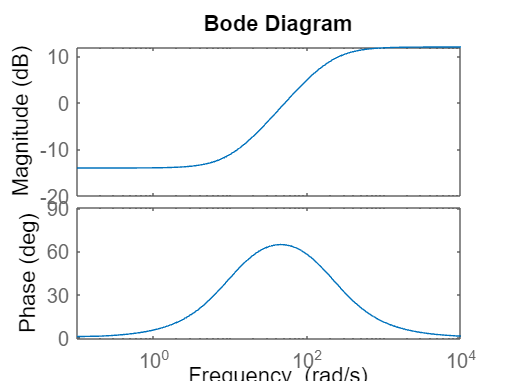

bode(W_i1) ;hold off;

bode(W_i2)

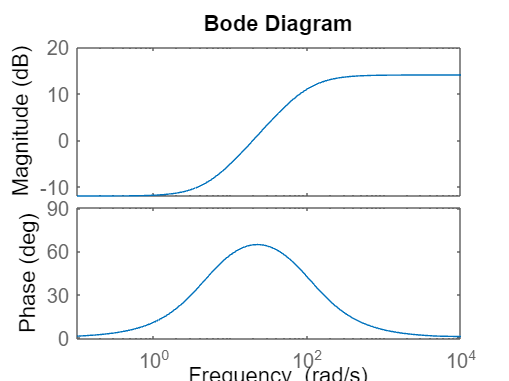

bode(W_o1)

bode(W_o2)

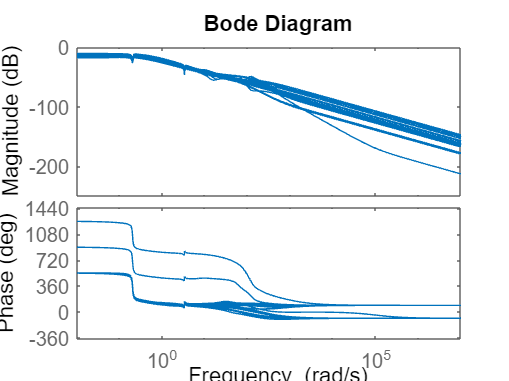


bode(Gp_bode)

## Singular value plot

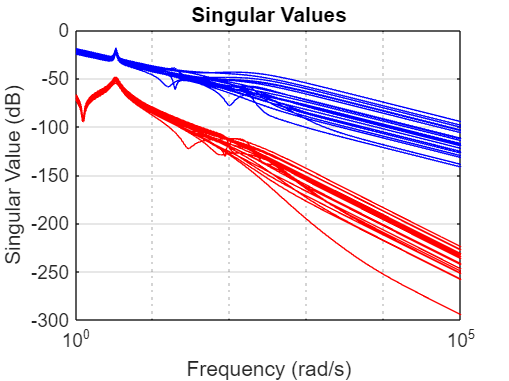

N = 20;
w = logspace(0, 5, 300);  

Gp_samples = usample(Gp, N);

svmax = zeros(length(w), N);
svmin = zeros(length(w), N);

for k = 1:N
    for indw = 1:length(w)
        Gjw = freqresp(Gp_samples(:,:,k), w(indw));
        s = svd(Gjw);
        svmax(indw,k) = s(1);
        svmin(indw,k) = s(end);
    end
end

figure
semilogx(w, 20*log10(svmax), 'b'); hold on
semilogx(w, 20*log10(svmin), 'r');
grid on
xlabel('Frequency (rad/s)')
ylabel('Singular Value (dB)')
title('Singular Values')

## NP, RP, RS

%NP
M_NP = M_frd(5:8, 5:6); 
blk_NP = [2 4];
[mu_NP_bounds, ~] = mussv(M_NP, blk_NP, 'c'); 

Points completed: 100/100


mu_NP_peak = norm(mu_NP_bounds(:,1), inf);   


%RS
M_RS = M_frd(1:4, 1:4);
blk_RS = [1 1; 1 1; 1 1; 1 1]; 
[mu_RS_bounds, ~] = mussv(M_RS, blk_RS, 'c'); 

Points completed: 100/100


mu_RS_peak = norm(mu_RS_bounds(:,1), inf);    

%RP
M_RP = M_frd;
blk_RP = [blk_RS; 2 4]; 
[mu_RP_bounds, ~] = mussv(M_RP, blk_RP, 'c');

Points completed: 100/100


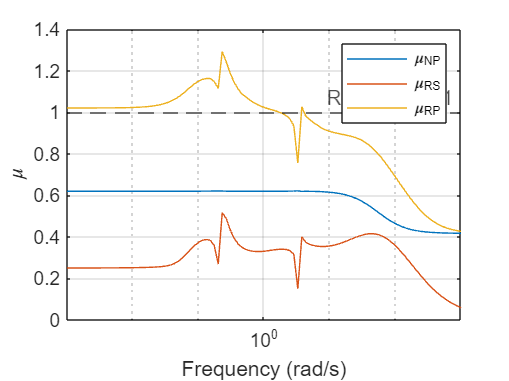

mu_RP_peak = norm(mu_RP_bounds(:,1), inf);    

figure();
semilogx(mu_NP_bounds(1)); hold on;
semilogx(mu_RS_bounds(1)); 
semilogx(mu_RP_bounds(1));
yline(1, '--k', 'Reference = 1');
xlim([10^-3, 10^3])
xlabel('Frequency (rad/s)'); 
ylabel('\mu');
legend('\mu_{NP}', '\mu_{RS}', '\mu_{RP}')
grid on;


% The code below is used to obtain some more information on the stability
% and perfomance analysis using robuststab and robustperf. This is gives mroe details and is useful
% for plotting and explaining some things in the report.
CL_rob = lft(P_rob, K_nom);

% Nominal Stability (NS)
% Check stability of nominal cl
if isstable(CL_rob.NominalValue)
    disp('NS: OK');
else
    disp('NS: FAILED');
end

NS: OK



% Nominal Performance (NP)
% H-inf norm of nominal cl
np_norm = norm(CL_rob.NominalValue, inf);
disp(['Nominal Performance (Gamma): ', num2str(np_norm)]);

Nominal Performance (Gamma): 0.62151


if np_norm < 1
    disp('NP: OK (<1)');
else
    disp('NP: Not met (>1)');
end

NP: OK (<1)



% Robust Stability (RS)
[stabmarg, destabunc, report, info] = robuststab(CL_rob);
disp('Robust Stability Report:');

Robust Stability Report:


disp(report);

System is robustly stable for the modeled uncertainty.                                 
 -- It can tolerate up to 193% of the modeled uncertainty.                             
 -- There is a destabilizing perturbation amounting to 193% of the modeled uncertainty.
 -- This perturbation causes an instability at the frequency 0.241 rad/seconds.        
 -- Sensitivity with respect to each uncertain element is:                             
      51% for delta_i1. Increasing delta_i1 by 25% decreases the margin by 12.8%.      
      69% for delta_i2. Increasing delta_i2 by 25% decreases the margin by 17.2%.      
      65% for delta_o1. Increasing delta_o1 by 25% decreases the margin by 16.2%.      
      0% for delta_o2. Increasing delta_o2 by 25% decreases the margin by 0%.          



% Robust Performance (RP)
[perfmarg, perfunc, report_perf, info_perf] = robustperf(CL_rob);
disp('Robust Performance Report:');

Robust Performance Report:


disp(report_perf);

Uncertain system does not achieve performance robustness to modeled uncertainty.                               
 -- The tradeoff of model uncertainty and system gain is balanced at a level of 77% of the modeled uncertainty.
 -- A model uncertainty of 77% can lead to input/output gain of 1.3 at 0.221 rad/seconds.                      
 -- Sensitivity with respect to each uncertain element is:                                                     
      17% for delta_i1. Increasing delta_i1 by 25% decreases the margin by 4.25%.                              
      22% for delta_i2. Increasing delta_i2 by 25% decreases the margin by 5.5%.                               
      25% for delta_o1. Increasing delta_o1 by 25% decreases the margin by 6.25%.                              
      6% for delta_o2. Increasing delta_o2 by 25% decreases the margin by 1.5%.                                


## Robust Controller Design (D-K Iteration) - Section 2.2


disp('-------------------------------------------------');

-------------------------------------------------


disp('Robust Controller Design (D-K Iteration)');

Robust Controller Design (D-K Iteration)



% Controller Synthesis

% Options for musyn
nmeas = 2;
ncont = 2;
opts = musynOptions('Display', 'short', 'MaxIter', 10);

[K_rob, CL_rob_opt, bnd] = musyn(P_rob, nmeas, ncont, opts);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           11.65        8.528        8.619            30
    2           4.153        4.093        4.123            24
    3           1.409        1.287        1.296            34
    4           1.028        1.021        1.031            34
    5          0.9745       0.9729       0.9773            38
    6          0.9637       0.9631       0.9647            38
    7          0.9612       0.9608        0.963            38
    8           0.961       0.9607       0.9629            38

Best achieved robust performance: 0.961




disp('D-K Iteration Complete.');

D-K Iteration Complete.



% Form closed loop with robust controller
CL_rob_final = lft(P_rob, K_rob);

% Nominal Stability (NS)
if isstable(CL_rob_final.NominalValue)
    disp('NS (Robust Controller): OK');
else
    disp('NS (Robust Controller): FAILED');
end

NS (Robust Controller): OK



% Nominal Performance (NP)
np_norm_rob = norm(CL_rob_final.NominalValue, inf);
disp(['Nominal Performance (Gamma) with Robust Controller: ', num2str(np_norm_rob)]);

Nominal Performance (Gamma) with Robust Controller: 0.73027



% Robust Stability (RS)
[stabmarg_rob, destabunc_rob, report_rob, info_rob] = robuststab(CL_rob_final);
disp('Robust Stability:');

Robust Stability:


disp(report_rob);

System is robustly stable for the modeled uncertainty.                                 
 -- It can tolerate up to 189% of the modeled uncertainty.                             
 -- There is a destabilizing perturbation amounting to 189% of the modeled uncertainty.
 -- This perturbation causes an instability at the frequency 102 rad/seconds.          
 -- Sensitivity with respect to each uncertain element is:                             
      44% for delta_i1. Increasing delta_i1 by 25% decreases the margin by 11%.        
      3% for delta_i2. Increasing delta_i2 by 25% decreases the margin by 0.75%.       
      57% for delta_o1. Increasing delta_o1 by 25% decreases the margin by 14.2%.      
      0% for delta_o2. Increasing delta_o2 by 25% decreases the margin by 0%.          



% Robust Performance (RP)
[perfmarg_rob, perfunc_rob, report_perf_rob, info_perf_rob] = robustperf(CL_rob_final);
disp('Robust Performance:');

Robust Performance:


disp(report_perf_rob);

Uncertain system achieves performance robustness to modeled uncertainty.                                        
 -- The tradeoff of model uncertainty and system gain is balanced at a level of 104% of the modeled uncertainty.
 -- A model uncertainty of 104% can lead to input/output gain of 0.961 at 4.87 rad/seconds.                     
 -- Sensitivity with respect to each uncertain element is:                                                      
      21% for delta_i1. Increasing delta_i1 by 25% decreases the margin by 5.25%.                               
      20% for delta_i2. Increasing delta_i2 by 25% decreases the margin by 5%.                                  
      27% for delta_o1. Increasing delta_o1 by 25% decreases the margin by 6.75%.                               
      9% for delta_o2. Increasing delta_o2 by 25% decreases the margin by 2.25%.                                


## Fixed structure controller synthesis (for comparison)

disp('Synthesizing Fixed Structure Controller (for comparison)');

Synthesizing Fixed Structure Controller (for comparison)



% Define variables
Kp1 = realp('Kp1',1);
Ki1 = realp('Ki1',1);
Kd1 = realp('Kd1',1);
Tf1 = realp('Tf1',1);

Kp2 = realp ('Kp2' ,1);
Ki2 = realp ('Ki2' ,1);
Kd2 = realp ('Kd2' ,1);
Tf2 = realp ('Tf2' ,1);

s = tf('s');

C11 = Kp1 + Ki1/s + (Kd1*s)/(Tf1*s + 1);
C21 = Kp2 + (Kd2*s)/(Tf2*s + 1);

% Re-define weights for synthesis (use same Wp, Wu from section 2)
Wp1_struc = Wp(1, 1) ;
Wp1_struc.u = 'e1';
Wp1_struc.y = 'z11';

Wp2_struc = Wp(2, 2) ;
Wp2_struc.u = 'e2';
Wp2_struc.y = 'z12';

Wu1_struc = Wu(1, 1) ;
Wu1_struc.u = 'u1';
Wu1_struc.y = 'z21';

Wu2_struc = Wu(2, 2) ;
Wu2_struc.u = 'u2';
Wu2_struc.y = 'z22';

% Redefine G for structured connection
G_mimo11 = -1* G(1, 1) ;
G_mimo11.u = 'u1';
G_mimo11.y = 'y11';

G_mimo12 = -1* G(1, 2) ;
G_mimo12.u = 'u2';
G_mimo12.y = 'y12';

G_mimo21 = -1* G(2,1) ;
G_mimo21.u = 'u1';
G_mimo21.y = 'y21';

G_mimo22 = -1* G(2, 2) ;
G_mimo22.u = 'u2';
G_mimo22.y = 'y22';

SumG_1 = sumblk('y1 = y11 + y12');
SumG_2 = sumblk('y2 = y21 + y22');

C_mimo1 = C11 ;
C_mimo1.u = 'v1';
C_mimo1.y = 'u1';

C_mimo2 = C21 ;
C_mimo2.u = 'v1';
C_mimo2.y = 'u2';

Sum1 = sumblk('e1 = r + y1'); 
Sum2 = sumblk('e2 = r + y2');
Sum3 = sumblk('v1 = -e1');

Mimo_Con = connect(Wp1_struc,Wp2_struc,Wu1_struc, Wu2_struc, ...
    G_mimo11, G_mimo12, G_mimo21, G_mimo22, ...
    C_mimo1, C_mimo2, SumG_1, SumG_2, Sum1, Sum2, Sum3, ...
    {'r'}, {'z11', 'z12', 'z21', 'z22'});

% Run H-Inf Struct Synthesis
opt = hinfstructOptions('Display','off','RandomStart', 5);
disp('Running hinfstruct');

Running hinfstruct


[N_mimo, gamma_struct, info_struct] = hinfstruct(Mimo_Con, opt);

% Extract controller gains
Kp_opt1 = N_mimo.Blocks.Kp1.Value; 
Ki_opt1 = N_mimo.Blocks.Ki1.Value; 
Kd_opt1 = N_mimo.Blocks.Kd1.Value; 
Tf_opt1 = N_mimo.Blocks.Tf1.Value; 

Kp_opt2 = N_mimo.Blocks.Kp2.Value; 
Kd_opt2 = N_mimo.Blocks.Kd2.Value; 
Tf_opt2 = N_mimo.Blocks.Tf2.Value; 

% Construct the fixed controller object
Kfb_opt_mimo = [Kp_opt1 + Ki_opt1 / s + ( Kd_opt1 * s ) /( Tf_opt1 * s +1), 0;
                Kp_opt2 + ( Kd_opt2 * s ) /( Tf_opt2 * s +1), 0];
K_fixed = ss(Kfb_opt_mimo);
disp(['Fixed Structure Gamma: ', num2str(gamma_struct)]);

Fixed Structure Gamma: 2.0313


## Robust performance comparison (including fixed structure)

disp('Calculating Robust Performance (\mu) for Fixed Structure Controller');

Calculating Robust Performance (\mu) for Fixed Structure Controller


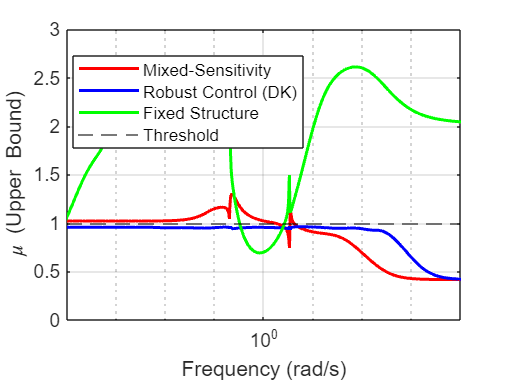


% Create closed loop for fixed structue
CL_fix_final = lft(P_rob, K_fixed);

% Run robustperf for fixed struc.
[~, ~, ~, info_perf_fix] = robustperf(CL_fix_final);

% Generate rob. performance plot for comparison
if exist('info_perf', 'var') && isfield(info_perf, 'MussvBnds') && ...
   exist('info_perf_rob', 'var') && isfield(info_perf_rob, 'MussvBnds') && ...
   exist('info_perf_fix', 'var') && isfield(info_perf_fix, 'MussvBnds')

    mubounds_nom = info_perf.MussvBnds;
    mubounds_rob = info_perf_rob.MussvBnds;
    mubounds_fix = info_perf_fix.MussvBnds;

    figure('Name', 'Robust_Performance_Comparison');
    
    % Mix-Sens
    if isa(mubounds_nom, 'frd'), [d, w] = freqresp(mubounds_nom); d=squeeze(d(1,2,:)); else, d=mubounds_nom(1,2).ResponseData(:); w=mubounds_nom.Frequency; end
    semilogx(w, d, 'r-', 'LineWidth', 1.5); hold on;
    
    % Robust (DK)
    if isa(mubounds_rob, 'frd'), [d, w] = freqresp(mubounds_rob); d=squeeze(d(1,2,:)); else, d=mubounds_rob(1,2).ResponseData(:); w=mubounds_rob.Frequency; end
    semilogx(w, d, 'b-', 'LineWidth', 1.5);

    % Fixed Struct
    if isa(mubounds_fix, 'frd'), [d, w] = freqresp(mubounds_fix); d=squeeze(d(1,2,:)); else, d=mubounds_fix(1,2).ResponseData(:); w=mubounds_fix.Frequency; end
    semilogx(w, d, 'g-', 'LineWidth', 1.5);
    
    % Threshold
    yline(1, 'k--');

    % title('Comparison of Robust Performance (\mu)');
    xlabel('Frequency (rad/s)');
    ylabel('\mu (Upper Bound)');
    xlim([1e-4, 1e4]);
    % ylim([1e-5, 1e5]); % User requested only x-limits
    legend('Mixed-Sensitivity', 'Robust Control (DK)', 'Fixed Structure', 'Threshold', 'Location', 'best');
    grid on;
else
    disp('Could not extract Mu bounds for comparison (one or more missing).');
end

## Time-Domain Simulations

K_nom.u = {'e(1)', 'e(2)'};
K_nom.y = {'u(1)', 'u(2)'};

K_rob.u = {'e(1)', 'e(2)'};
K_rob.y = {'u(1)', 'u(2)'};

K_fixed.u = {'e(1)', 'e(2)'};
K_fixed.y = {'u(1)', 'u(2)'};

% Nominal Simulation
disp('Running Nominal Simulations (stepWind)');

Running Nominal Simulations (stepWind)


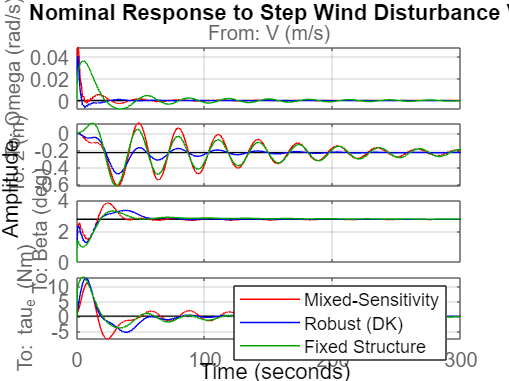


% 1. stepWind()
P_sim_nom = stepWind(FWT, K_nom, 'noplot', false); 
P_sim_rob = stepWind(FWT, K_rob, 'noplot', false); 
P_sim_fix = stepWind(FWT, K_fixed, 'noplot', false);

% 2. sineWInd()
omega = 0.221; % Frequency in rad/s
[P_sin_nom, Y_sin_nom, t_sin] = sineWind(FWT, K_nom, omega, 1, 300, 'noplot', false);
[P_sin_rob, Y_sin_rob, ~]    = sineWind(FWT, K_rob, omega, 1, 300, 'noplot', false);
[P_sin_fix, Y_sin_fix, ~]    = sineWind(FWT, K_fixed, omega, 1, 300, 'noplot', false);
% -----------------------------------------------

% Plot stepWind (sineWind plotted later since uncertain and nonimal is combined into 1 plot)
figure('Name', 'Nominal_StepWind_Comparison');
step(P_sim_nom, 'r-', P_sim_rob, 'b-', P_sim_fix, 'g-', 300);
legend('Mixed-Sensitivity', 'Robust (DK)', 'Fixed Structure', 'Location', 'east');
title('Nominal Response to Step Wind Disturbance V');
grid on; 


% Uncertain Simulation (Random Samples)
disp('Running Uncertain Simulations (Random Samples)');

Running Uncertain Simulations (Random Samples)


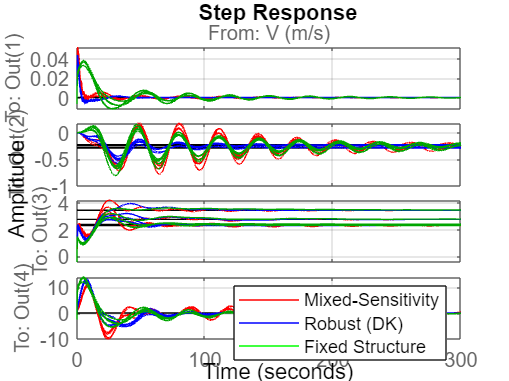


% Construct Uncertain FWT (Physical Plant + Weights) to be used with stepWind
% We reuse the uncertainty blocks defined earlier but applied to FWT structure
% FWT is inputs: [beta, tau, V], outputs: [Omega, z]
% Uncertainty is on inputs u=[beta, tau] and outputs y=[Omega, z].

FWT_InputUnc = blkdiag(eye(2) + W_in * blkdiag(delta_i1, delta_i2), 1); % 3 inputs, last one (V) is 1 (no unc)
FWT_OutputUnc = eye(2) + W_out * blkdiag(delta_o1, delta_o2);

FWT_unc = FWT_OutputUnc * FWT * FWT_InputUnc; 

num_samples = 5;
FWT_rand = usample(FWT_unc, num_samples);

figure('Name', 'Uncertain_Response_StepWind');
title(['Uncertain Response to Step Wind (', num2str(num_samples), ' Samples)']);

% Get array of CL systems for each controller
P_sim_unc_nom = stepWind(FWT_rand, K_nom, 'noplot', false); 
P_sim_unc_rob = stepWind(FWT_rand, K_rob, 'noplot', false); 
P_sim_unc_fix = stepWind(FWT_rand, K_fixed, 'noplot', false);

% Sine wind simulations (uncertain samples) @ omega (rad/s)
[P_sin_unc_nom, Y_sin_unc_nom, ~] = sineWind(FWT_rand, K_nom, omega, 1, 300, 'noplot', false);
[P_sin_unc_rob, Y_sin_unc_rob, ~] = sineWind(FWT_rand, K_rob, omega, 1, 300, 'noplot', false);
[P_sin_unc_fix, Y_sin_unc_fix, ~] = sineWind(FWT_rand, K_fixed, omega, 1, 300, 'noplot', false);
% -----------------------------------------------------------------------------------

% Plot uncertain step responses together
step(P_sim_unc_nom, 'r-', P_sim_unc_rob, 'b-', P_sim_unc_fix, 'g-', 300); 

% Used to get correct legend data:
hold on;
h1 = plot(nan, nan, 'r-');
h2 = plot(nan, nan, 'b-');
h3 = plot(nan, nan, 'g-');
legend([h1, h2, h3], 'Mixed-Sensitivity', 'Robust (DK)', 'Fixed Structure', 'Location', 'east');
grid on;

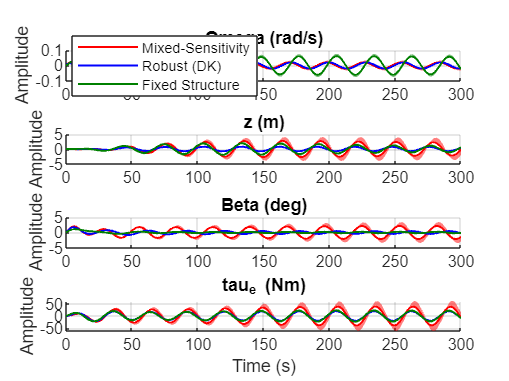


% -------------------------------------------------------------------------
% SineWind Comparison Figure: overlay nominal traces for all three
% controllers per subplot and shade uncertain responses as envelopes.
% -------------------------------------------------------------------------
try
    nout = size(Y_sin_nom,2);
    output_names = P_sin_nom.OutputName;
    if isempty(output_names) || length(output_names) ~= nout
        output_names = cell(1,nout);
        for ii=1:nout, output_names{ii} = sprintf('Output %d', ii); end
    end

    FigureName = sprintf('SineWind_Comparison_w=%.3f_radps', omega);
    figure('Name', FigureName);

    colors = {[1 0 0],[0 0 1],[0 0.5 0]}; % r, b, g
    labels = {'Mixed-Sensitivity', 'Robust (DK)', 'Fixed Structure'};

    for i = 1:nout
        subplot(nout,1,i);
        hold on;

        % Plot uncertain envelope for Mixed-Sensitivity (red)
        if exist('Y_sin_unc_nom','var') && ~isempty(Y_sin_unc_nom)
            y_min = squeeze(min(Y_sin_unc_nom(:,i,:),[],3));
            y_max = squeeze(max(Y_sin_unc_nom(:,i,:),[],3));
            x = [t_sin; flipud(t_sin)];
            y = [y_min; flipud(y_max)];
            fill(x, y, colors{1}, 'FaceAlpha', 0.50, 'EdgeColor', 'none');
        end
        % Nominal trace (Mixed-Sensitivity)
        h_nom = plot(t_sin, squeeze(Y_sin_nom(:,i,1)), '-', 'Color', colors{1}, 'LineWidth', 1);

        % Robust DK (blue)
        if exist('Y_sin_unc_rob','var') && ~isempty(Y_sin_unc_rob)
            y_min = squeeze(min(Y_sin_unc_rob(:,i,:),[],3));
            y_max = squeeze(max(Y_sin_unc_rob(:,i,:),[],3));
            x = [t_sin; flipud(t_sin)];
            y = [y_min; flipud(y_max)];
            fill(x, y, colors{2}, 'FaceAlpha', 0.50, 'EdgeColor', 'none');
        end
        h_rob = plot(t_sin, squeeze(Y_sin_rob(:,i,1)), '-', 'Color', colors{2}, 'LineWidth', 1);

        % Fixed Structure (green)
        if exist('Y_sin_unc_fix','var') && ~isempty(Y_sin_unc_fix)
            y_min = squeeze(min(Y_sin_unc_fix(:,i,:),[],3));
            y_max = squeeze(max(Y_sin_unc_fix(:,i,:),[],3));
            x = [t_sin; flipud(t_sin)];
            y = [y_min; flipud(y_max)];
            fill(x, y, colors{3}, 'FaceAlpha', 0.50, 'EdgeColor', 'none');
        end
        h_fix = plot(t_sin, squeeze(Y_sin_fix(:,i,1)), '-', 'Color', colors{3}, 'LineWidth', 1);

        title(output_names{i});
        if i == nout
            xlabel('Time (s)');
        end
        ylabel('Amplitude');
        if i == 1
            legend([h_nom, h_rob, h_fix], labels, 'Location', 'best');
        end
        grid on; hold off;
    end
catch ME
    disp('Could not produce SineWind comparison figure: %s');
end

## Frequency domain analysis - upper bound SSVs

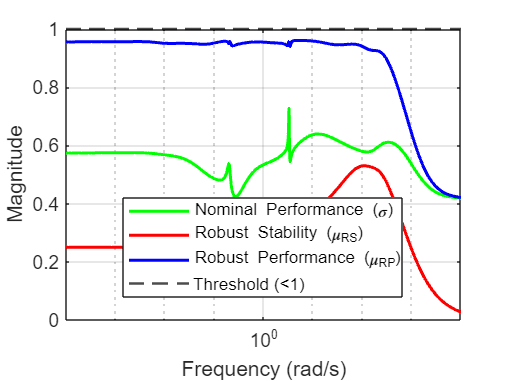

if exist('info_rob', 'var') && exist('info_perf_rob', 'var')
    figure('Name', 'SSV Analysis (NS, NP, RS, RP)');
    
    h_plots = [];
    legend_entries = {};
    
    np_sys = CL_rob_final.NominalValue;
    [sv, w_sv] = sigma(np_sys); 
    sv_max = sv(1,:); 
    
    h_np = semilogx(w_sv, sv_max, 'g-', 'LineWidth', 1.5);
    hold on;
    h_plots = [h_plots, h_np];
    legend_entries{end+1} = 'Nominal Performance (\sigma)';
    
    if isfield(info_rob, 'MussvBnds')
        mubounds_rs = info_rob.MussvBnds;
        if isa(mubounds_rs, 'frd')
            [rs_data, w_rs] = freqresp(mubounds_rs);
            rs_upper = squeeze(rs_data(1,2,:));
            freq_rs = w_rs; 
        else
            rs_upper = mubounds_rs(1,2).ResponseData(:);
            freq_rs = mubounds_rs.Frequency;
        end
        h_rs = semilogx(freq_rs, rs_upper, 'r-', 'LineWidth', 1.5);
        h_plots = [h_plots, h_rs];
        legend_entries{end+1} = 'Robust Stability (\mu_{RS})';
    end
    
    if isfield(info_perf_rob, 'MussvBnds')
        mubounds_rp = info_perf_rob.MussvBnds;
        if isa(mubounds_rp, 'frd')
            [rp_data, w_rp] = freqresp(mubounds_rp);
            rp_upper = squeeze(rp_data(1,2,:));
            freq_rp = w_rp;
        else
            rp_upper = mubounds_rp(1,2).ResponseData(:);
            freq_rp = mubounds_rp.Frequency;
        end
        h_rp = semilogx(freq_rp, rp_upper, 'b-', 'LineWidth', 1.5);
        h_plots = [h_plots, h_rp];
        legend_entries{end+1} = 'Robust Performance (\mu_{RP})';
    end
    
    h_th = yline(1, 'k--', 'LineWidth', 1.2);
    h_plots = [h_plots, h_th];
    legend_entries{end+1} = 'Threshold (<1)';
    
    xlabel('Frequency (rad/s)');
    ylabel('Magnitude');
    xlim([1e-4, 1e4]);
    legend(h_plots, legend_entries, 'Location', 'best');
    grid on;
    hold off;
end

## Functions

*Note: these functions were created using a combination of the original stepWind function given in the assignment, AI generated content, and code produced by the authors of this report.

function [P_sim] = stepWind(FWT, K, lineSpec, printTable)
% STEPWIND Applies a wind step disturbance to the closed loop consisting of
% the FWT and a controller K of choice (may be SISO or MIMO).
% Usage: [P_sim] = stepWind(FWT, K, lineSpec, printTable)
% lineSpec: string, e.g., 'r-' (optional). If empty or 'noplot', no plot is made.
% printTable: boolean, true to print metrics (optional, default true)

if nargin < 3
    lineSpec = 'b'; % Default
end
if nargin < 4
    printTable = true;
end

if size(K,1) == 1 % adapt if SISO
    K = blkdiag(K,0);
end
G = FWT(:,1:2);

% Contstruct CL for simulation
G_sim = G;
G_sim.u = 'u';
G_sim.y = 'y_plant';

K_sim = K;
K_sim.u = 'y_meas';
K_sim.y = 'u';

Gd_sim = FWT(:,3);
Gd_sim.u = 'V';
Gd_sim.y = 'y_dist';

Sum_sim = sumblk('y_meas = y_plant + y_dist', 2);

P_sim = connect(G_sim,K_sim,Gd_sim,Sum_sim,{'V'},{'y_meas','u'});

P_sim.InputName = {'V (m/s)'};
if ~isempty(G.OutputName)
    P_sim.OutputName = [G.OutputName; G.InputName];
end


% Plotting
if ~strcmpi(lineSpec, 'noplot') && ~isempty(lineSpec)
    step(P_sim, lineSpec, 300);
end

if printTable
    % Get response data (simulated for 300s)
    [y, t] = step(P_sim, 300);
    [~, n_out, n_sys] = size(y);
    
    if n_sys > 1
        % If array of systems, skip table or print first (handling arrays is complex for table)
        return; 
    end

    % Loop through outputs to calculate stepinfo
    for i = 1:n_out
        y_i = y(:, i);
        peak_val = max(abs(y_i));
        final_val = y_i(end);
        
        % Check for Disturbance Rejection (Impulse-like) vs Step Tracking
        % If final value is small (< 5% of peak), treat as settling to zero (Disturbance).
        is_disturbance = (peak_val > 0) && (abs(final_val) < 0.05 * peak_val);
        
        if is_disturbance
            % Disturbance Rejection: Use user-defined Recovery Time and Peak Deviation
            y0 = final_val;
            e = y_i - y0;
            
            % Peak deviation
            peak_dev = max(abs(e));
            
            % Recovery time (2% band of peak deviation)
            eps_bound = 0.02 * peak_dev;
            idx = find(abs(e) > eps_bound, 1, 'last');
            if isempty(idx)
                recovery_time = 0;
            else
                recovery_time = t(idx);
            end
            
            % Get a template structure from stepinfo to ensure compatibility
            si = stepinfo(y_i, t, final_val, 'SettlingTimeThreshold', 0.02);
            
            % Overwrite with custom metrics
            si.SettlingTime = recovery_time;
            si.Peak = peak_dev;
            si.Overshoot = NaN; 
            
            % Calculate Rise Time manually (10% to 90% of Peak Deviation)
            [~, idx_peak] = max(abs(e));
            abs_e = abs(e);
            idx_10 = find(abs_e(1:idx_peak) >= 0.1 * peak_dev, 1, 'first');
            idx_90 = find(abs_e(1:idx_peak) >= 0.9 * peak_dev, 1, 'first');
            
            if ~isempty(idx_10) && ~isempty(idx_90)
                si.RiseTime = t(idx_90) - t(idx_10);
            else
                si.RiseTime = NaN;
            end
        else
            % Standard Step Tracking
            si = stepinfo(y_i, t, final_val, 'SettlingTimeThreshold', 0.02);
        end
        
        % Store Final Value
        si.FinalValue = final_val;
    
        if i == 1
            S = si;
            S(n_out) = si; % Preallocate structure array
        else
            S(i) = si;
        end
    end
    
    % Format and display table
    fprintf('\n================================================================================================================================\n');
    fprintf('                                        Step Response Performance Metrics (2%% Settling)                                        \n');
    fprintf('================================================================================================================================\n');
    fprintf('%-25s | %-10s | %-10s | %-10s | %-10s | %-10s | %-10s | %-10s\n', ...
        'Output Channel', 'RiseTime', 'Recov/Set', 'Overshoot%', 'Undershoot%', 'Peak/Dev', 'PeakTime', 'FinalValue');
    fprintf('--------------------------|------------|------------|------------|------------|------------|------------|------------\n');
    
    output_names = P_sim.OutputName;
    % Handle case where OutputName might be empty or not set correctly
    if isempty(output_names) || length(output_names) ~= length(S)
        output_names = cell(length(S), 1);
        for i=1:length(S), output_names{i} = sprintf('Output %d', i); end
    end
    
    for i = 1:length(S)
        fprintf('%-25s | %-10.4f | %-10.4f | %-10.4f | %-10.4f | %-10.4f | %-10.4f | %-10.4f\n', ...
            output_names{i}, S(i).RiseTime, S(i).SettlingTime, S(i).Overshoot, S(i).Undershoot, S(i).Peak, S(i).PeakTime, S(i).FinalValue);
    end
    fprintf('================================================================================================================================\n');
end
end


%% SINEWIND Applies a sinusoidal wind disturbance on the wind channel (V)
function [P_sim, Y, t] = sineWind(FWT, K, omega, amp, tFinal, lineSpec, printTable)
% SINEWIND Simulates a sinusoidal disturbance on the third input channel (wind V)
% Usage: [P_sim, Y, t] = sineWind(FWT, K, omega, amp, tFinal, lineSpec, printTable)
% omega: angular frequency in rad/s (default 0.221)
% amp: amplitude of sinusoid (default 1)
% tFinal: simulation length in seconds (default 300)
% lineSpec: plot style (use 'noplot' to suppress plotting)
% printTable: logical to print summary (default true)

if nargin < 3 || isempty(omega), omega = 0.221; end
if nargin < 4 || isempty(amp), amp = 1; end
if nargin < 5 || isempty(tFinal), tFinal = 300; end
if nargin < 6 || isempty(lineSpec), lineSpec = 'b'; end
if nargin < 7, printTable = true; end

% Adapt SISO controller if necessary (same convention as stepWind)
if size(K,1) == 1
    K = blkdiag(K,0);
end

% Build closed-loop plant for disturbance input V (third input)
G = FWT(:,1:2);
G_sim = G; G_sim.u = 'u'; G_sim.y = 'y_plant';
K_sim = K; K_sim.u = 'y_meas'; K_sim.y = 'u';
Gd_sim = FWT(:,3); Gd_sim.u = 'V'; Gd_sim.y = 'y_dist';
Sum_sim = sumblk('y_meas = y_plant + y_dist', 2);
P_sim = connect(G_sim, K_sim, Gd_sim, Sum_sim, {'V'}, {'y_meas','u'});
P_sim.InputName = {'V (m/s)'};
if ~isempty(G.OutputName)
    P_sim.OutputName = [G.OutputName; G.InputName];
end

% Time vector and input
period = 2*pi/ max(omega, eps); % avoid division by zero
Ts = min(0.01, period/100);
t = (0:Ts:tFinal)';
u = amp * sin(omega * t);

% Simulate for each model in the LTI array (handle array of plants)
[n_out, ~, n_sys] = size(P_sim);
Y = zeros(length(t), n_out, n_sys);

for kk = 1:max(1,n_sys)
    try
        [y_tmp, ~] = lsim(P_sim(:,:,kk), u, t);
    catch
        % Some MATLAB versions don't accept paren indexing on certain I/O models
        % Fall back to using lsim with array support (may replicate across systems)
        [y_all, ~] = lsim(P_sim, u, t);
        if ndims(y_all) == 3
            y_tmp = y_all(:,:,min(kk,size(y_all,3)));
        else
            % If still ambiguous, use first set
            y_tmp = y_all;
        end
    end
    Y(:,:,kk) = y_tmp;
end

% Plotting (only when requested) - match layout of stepWind (one subplot per output)
if ~strcmpi(lineSpec, 'noplot') && ~isempty(lineSpec)
    figure('Name', sprintf('SineWind (w=%.3f rad/s)', omega));
    nout = size(Y,2);

    output_names = P_sim.OutputName;
    if isempty(output_names) || length(output_names) ~= nout
        output_names = cell(1, nout);
        for ii = 1:nout, output_names{ii} = sprintf('Output %d', ii); end
    end

    for i = 1:nout
        subplot(nout,1,i);
        hold on;
        % If there are multiple uncertain samples/systems, plot all traces
        if n_sys > 1
            % squeeze gives [time x n_sys]
            plot(t, squeeze(Y(:,i,:)));
        else
            plot(t, squeeze(Y(:,i,1)), lineSpec);
        end
        title(output_names{i});
        if i == nout
            xlabel('Time (s)');
        end
        ylabel('Amplitude');
        grid on; hold off;
    end
end

% Print simple summary if requested
if printTable
    fprintf('\n--- SineWind (w=%.3f rad/s) Summary ---\n', omega);
    for i = 1:size(Y,2)
        peak_val = max(abs(Y(:,i,1)));
        fprintf('%-25s | Peak: %8.4f\n', P_sim.OutputName{i}, peak_val);
    end
    fprintf('---------------------------------------\n');
end

end
